load data\system_parameters.mat
load data\fwdKin_symbolic.mat
addpath inc\

syms x y z
syms theta_1  theta_2 theta_3 theta_4

m_1=0.060;m_3=0.080; m_2=m_3; m_4 = 0.040; % weight of the masses in Kg

l_1 = -0.02; l_2=-0.03; l_3=l_2; l_4=-0.025; l_5 = 0.015; % distance from joint to CM d_5 is lateral




%Transfromation from frame_i to CM_i
T1_c1 = T.T10*trans(y,l_1);
T2_c2 = T.T20*trans(x,l_2);
T3_c3 = T.T30*trans(x,l_3);
T4_c4 = T.T40*trans(x,l_4)*trans(y,l_5);




This section plots the frames and the CM frames to make sure I am not doing any thing wrong 

every varible with _t mean test varible as in testing to make sure I am not dumb.

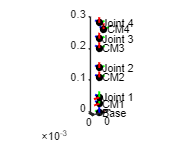

% Define the substitution values for theta variables
subs_values = [pi, 0, 0, 0];
theta_vars = [theta_1, theta_2, theta_3, theta_4];

% Substitute values into each transformation matrix
T.T10_t = subs(T.T10, theta_vars, subs_values);
T.T20_t = subs(T.T20, theta_vars, subs_values);
T.T30_t = subs(T.T30, theta_vars, subs_values);
T.T40_t = subs(T.T40, theta_vars, subs_values);

T1_c1_t = subs(T1_c1, theta_vars, subs_values);
T2_c2_t = subs(T2_c2, theta_vars, subs_values);
T3_c3_t = subs(T3_c3, theta_vars, subs_values);
T4_c4_t = subs(T4_c4, theta_vars, subs_values);



% Initialize figure
figure;
axis equal;
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Robot Arm Transformation Visualization');

% Plot base frame
plotFrame(eye(4), 'Base');

% Plot each joint frame
plotFrame(T.T10_t, 'Joint 1');
plotFrame(T.T20_t, 'Joint 2');
plotFrame(T.T30_t, 'Joint 3');
plotFrame(T.T40_t, 'Joint 4');

% Plot center of mass frames for each link (e.g., T1_c1, T2_c2, etc.)
plotFrame(T1_c1_t, 'CM1');
plotFrame(T2_c2_t, 'CM2');
plotFrame(T3_c3_t, 'CM3');
plotFrame(T4_c4_t, 'CM4');

% Adjust view
view(3);
axis equal;

#### **Jacobian for each CM**

zVec=[0 0 0 0 0 0]';
z0=[0 0 1]'

z0 =      0
     0
     1


o0=[0 0 0]';
o1 = T.T10(1:3,4);
o2 = T.T20(1:3,4);
o3 = T.T30(1:3,4);
z1=T.T10(1:3,3);
z2 = T.T20(1:3,3);
z3 = T.T30(1:3,3);

O_cm1=T1_c1(1:3,4);
O_cm2=T2_c2(1:3,4);
O_cm3=T3_c3(1:3,4);
O_cm4=T4_c4(1:3,4);

J_cm1 = [J_i(z0,O_cm1,o0,"revolute"),zVec,zVec,zVec];
J_cm2=[J_i(z0,O_cm2,o0,"revolute"),J_i(z1,O_cm2,o1,"revolute"),zVec,zVec];
J_cm3=[J_i(z0,O_cm3,o0,"revolute"),J_i(z1,O_cm3,o1,"revolute"),J_i(z2,O_cm3,o2,"revolute"),zVec];
J_cm4=[J_i(z0,O_cm4,o0,"revolute"),J_i(z1,O_cm4,o1,"revolute"),J_i(z2,O_cm4,o2,"revolute"),J_i(z3,O_cm4,o3,"revolute")];

%split the jac into velocity and angular velocity
  
J_v={simplify(J_cm1(1:3,:)) simplify(J_cm2(1:3,:)) simplify(J_cm3(1:3,:)) simplify(J_cm4(1:3,:))};
J_w={simplify(J_cm1(4:6,:)) simplify(J_cm2(4:6,:)) simplify(J_cm3(4:6,:)) simplify(J_cm4(4:6,:))};

#### Inertia tensor

Now this is the part I am unsure of since I don't know the width of the links. This why maybe he said as realisticly as possible ?

I will use Uniform Rectangular Solid i am going to assum desity is the same and estimate the shapes as rects and assume the width is 1/10 of the robot length 286mm so the width would be 28.6mm let's say 30mm to make it easy 

w = 0.03; %this is the width
I0 = (m_1/12)*(w^2+p.d1^2); %30mm*50mm
I0=eye(3)*I0;
%inserting the inertia tensor in the given matrices
D1=[1 0 0;0 0.4 0;0 0 0.9]*I0;
D2=[0.45 0 0;0 1.4 0;0 0  1.2]*I0;
D3=[0.45 0 0;0 1.4 0;0 0  1.2]*I0;
D4=[0.5 0 0;0 0.5 0;0 0 0.5]*I0;

## Finishing the D

%rotation matrices
R_cm1=T1_c1(1:3,1:3);
R_cm2=T2_c2(1:3,1:3);
R_cm3=T3_c3(1:3,1:3);
R_cm4=T4_c4(1:3,1:3);

% \fancy{I}=RIR'
I1=vpa(simplify(R_cm1*D1*R_cm1'),3);
I2=vpa(simplify(R_cm2*D2*R_cm2'),3);
I3=vpa(simplify(R_cm3*D3*R_cm3'),3);
I4=vpa(simplify(R_cm4*D4*R_cm4'),3);

I={I1 I2 I3 I4};
m =[m_1 m_2 m_3 m_4];
%Computing the D
% Define the number of links in your system
n = 4;

% Initialize D(q) as a zero matrix of appropriate size (usually n x n)
D = zeros(n);

% Loop over each link
for i = 1:n
    % Define the parameters for link i (these would be precomputed or given)
    % m_i: mass of link i
    % J_vi: linear velocity Jacobian of link i
    % J_wi: angular velocity Jacobian of link i
    % R_i: rotation matrix from body frame of link i to the inertial frame
    % I_i: inertia tensor in the body frame of link i

    % For demonstration purposes, assume m_i, J_vi, J_wi, R_i, and I_i are
    % symbolic or numerical matrices/vectors defined previously in your code.

    % Compute the first term: m_i * J_vi' * J_vi
    term1 = m(i) * (J_v{i}' * J_v{i});
  

    % Compute the second term: J_wi' * R_i * I_i * R_i' * J_wi
    term2 = J_w{i}' * I{i} * J_w{i};
    
    % Add the terms to the summation
    D = D + (term1 + term2);
end

% Display the result
%simplify(D);
disp('D(q) matrix:');

D(q) matrix:


disp(D);

#### Gravity 

Take note that gravity will act differnt on each joint depending on the rotation thus we have 3 g vectors

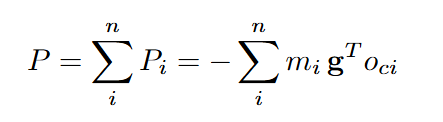

g_x=[-9.81 0 0]; % for cm2 cm3 cm4 % my g seem to be the reason why this give weird result
g_y=[0 -9.81 0]; % for cm1

P=-(m_1*g_y*O_cm1+m_2*g_x*O_cm2+m_3*g_x*O_cm3+m_4*g_x*O_cm4);

g=[simplify(diff(P,theta_1)) simplify(diff(P,theta_2)) simplify(diff(P,theta_3)) simplify(diff(P,theta_4))];
g=simplify(g);


#### Christoffel symbols

syms theta_1_dot theta_2_dot theta_3_dot theta_4_dot
q=[theta_1 theta_2 theta_3 theta_4];
q_dot=[theta_1_dot theta_2_dot theta_3_dot theta_4_dot];
C=Christoffel(D,q,q_dot);

Next last step

syms theta_ddot_1 theta_ddot_2 theta_ddot_3 theta_ddot_4
q_ddot = [theta_ddot_1 theta_ddot_2 theta_ddot_3 theta_ddot_4];

tau = D*q_ddot' + C*q_dot' + g;

tau_1=tau(1);
tau_2=tau(2);
tau_3=tau(3);
tau_4=tau(4);
% Save tau components to a .mat file in the "data" directory
save('data/tau_values.mat', 'tau_1', 'tau_2', 'tau_3', 'tau_4');


#### Ploting

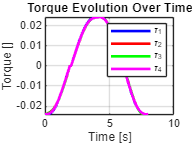

load("data\circle_points.mat")
load('data\p10_p6.mat')%t is 21 long
%load('data\tau_values.mat')
load('data\testing.mat')
steps=84;

% Initialize tau_array with zeros
tau_array = zeros(steps, 4);
tau_array_t = zeros(steps, 4);
for i = 1:84
    % Extract the current values of q, q_dot, and q_ddot for the ith time step
    q_i = qAB_5(:,i)';
    q_dot_i = qAB_5_d(:,i)';
    q_ddot_i = qAB_5_dd(:,i)';
    
    % Substitute values for q, q_dot, and q_ddot at step i
    %tau_1_eval = subs(tau_1, [q q_dot q_ddot], [q_array(i,:) q_dot_array(i,:) q_ddot_array(i,:)]);
    %tau_2_eval = subs(tau_2, [q q_dot q_ddot], [q_array(i,:) q_dot_array(i,:) q_ddot_array(i,:)]);
    %tau_3_eval = subs(tau_3, [q q_dot q_ddot], [q_array(i,:) q_dot_array(i,:) q_ddot_array(i,:)]);
    %tau_4_eval = subs(tau_4, [q q_dot q_ddot], [q_array(i,:) q_dot_array(i,:) q_ddot_array(i,:)]);

    tau_1_eval_t = subs(tau_1, [q q_dot q_ddot], [q_i q_dot_i q_ddot_i]);    
    tau_2_eval_t = subs(tau_2, [q q_dot q_ddot], [q_i q_dot_i q_ddot_i]);
    tau_3_eval_t = subs(tau_3, [q q_dot q_ddot], [q_i q_dot_i q_ddot_i]);
    tau_4_eval_t = subs(tau_4, [q q_dot q_ddot], [q_i q_dot_i q_ddot_i]);
    
    % Store the evaluated tau values in the tau_array
    %tau_array(i,:) = [tau_1_eval, tau_2_eval, tau_3_eval, tau_4_eval];
    tau_array_t(i,:) = [tau_1_eval_t, tau_2_eval_t, tau_3_eval_t, tau_4_eval_t];
end




% Plot
time = linspace(0, 8, steps);

% Plot each torque column
figure;
plot(time, tau_array_t(:, 1), 'b', 'LineWidth', 2); 
hold on;
plot(time, tau_array_t(:, 2), 'r', 'LineWidth', 2);
plot(time, tau_array_t(:, 3), 'g', 'LineWidth', 2); 
plot(time, tau_array_t(:, 4), 'm', 'LineWidth', 2);

title('Torque Evolution Over Time');
xlabel('Time [s]');
ylabel('Torque []');
legend('\tau_1', '\tau_2', '\tau_3', '\tau_4');
grid on;
hold off;

% Concatenate all tau expressions into a single vector
tau_all = [tau_1; tau_2; tau_3; tau_4];

% Get all symbolic variables in tau_all
all_symbols = symvar(tau_3);

% Find unique symbolic variables
unique_symbols = unique(all_symbols);

% Display the unique symbols
disp('Unique symbolic variables in tau:');
disp(unique_symbols);

function plotFrame(T, frameName)
    %Function to plot frames on to a 3d plot to easly understand what is
    %going on
    % Extract the origin from the transformation matrix
    origin = T(1:3, 4);
    
    % Extract x, y, and z axes from the rotation matrix part of T
    xAxis = T(1:3, 1) * 0.02; % Scale for visualization
    yAxis = T(1:3, 2) * 0.02;
    zAxis = T(1:3, 3) * 0.02;
    
    % Plot the origin
    plot3(origin(1), origin(2), origin(3), 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
    hold on;
    
    % Plot the x, y, and z axes as red, green, and blue arrows
    quiver3(origin(1), origin(2), origin(3), xAxis(1), xAxis(2), xAxis(3), 'r', 'LineWidth', 1.5);
    quiver3(origin(1), origin(2), origin(3), yAxis(1), yAxis(2), yAxis(3), 'g', 'LineWidth', 1.5);
    quiver3(origin(1), origin(2), origin(3), zAxis(1), zAxis(2), zAxis(3), 'b', 'LineWidth', 1.5);
    
    % Add a text label for the frame
    text(origin(1), origin(2), origin(3), [' ' frameName], 'FontSize', 8);
end


function C = Christoffel(D, q, q_dot)
    % CHRISTOFFEL Computes the Christoffel matrix C based on the input D(q) matrix
    %
    % Inputs:
    %   D     - Inertia matrix (symbolic or numeric) as a function of q
    %   q     - Vector of generalized coordinates (symbolic or numeric)
    %   q_dot - Vector of generalized velocities (numeric)
    %
    % Output:
    %   C - Christoffel matrix

    % Get the number of coordinates
    n = length(q);
    
    % Initialize Christoffel matrix C as a zero matrix
    C = sym(zeros(n, n));
    
    % Compute Christoffel symbols
    for k = 1:n
        for j = 1:n
            c_kj = 0;
            for i = 1:n
                % Partial derivatives of D matrix elements
                dD_kj_dqi = diff(D(k,j), q(i));
                dD_ki_dqj = diff(D(k,i), q(j));
                dD_ij_dqk = diff(D(i,j), q(k));
                
                % Compute c_kj term for the current i
                c_kj = c_kj + 0.5 * (dD_kj_dqi + dD_ki_dqj - dD_ij_dqk) * q_dot(i);
            end
            % Assign the computed Christoffel term to the C matrix
            C(k,j) = c_kj;
        end
    end

    % Simplify the Christoffel matrix (optional, especially for symbolic computation)
    %C = simplify(C);
end

